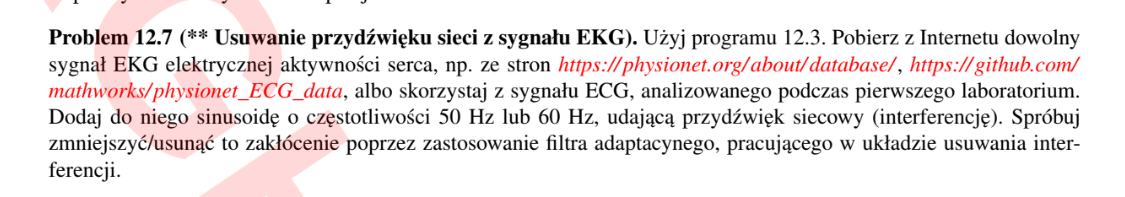

clear all;
load("ECG100.mat");
whos

  Name      Size                Bytes  Class     Attributes

  val       2x21600            345600  double              



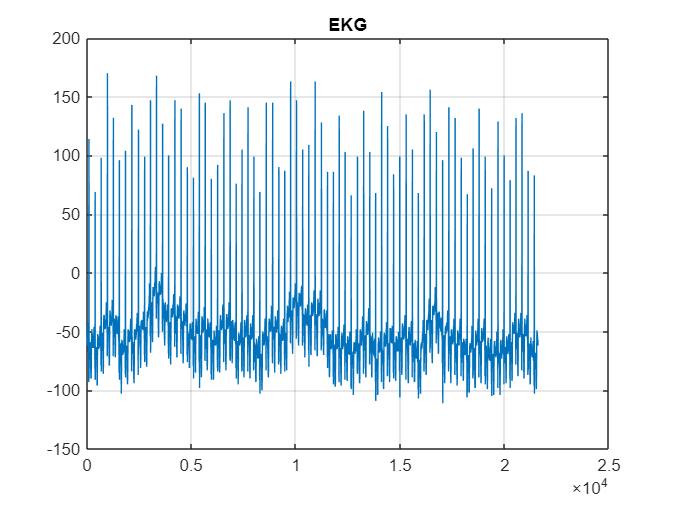

ekg = val(2,:);
plot(ekg); title('EKG'); grid;

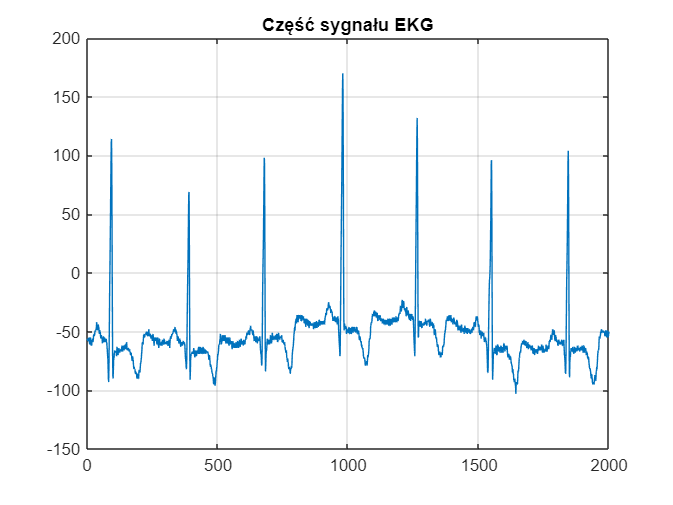

plot(ekg(1:2000)); title('Część sygnału EKG'); grid;

Sinusoidę o częstotliwości 50 Hz dodajemy do sygnału EKG. Ta sinusoida będzie sygnałem interferującym `d`, a sygnał pomocniczy `x` będzie zawierał tylko tę sinusoidę (lub jej kopię).

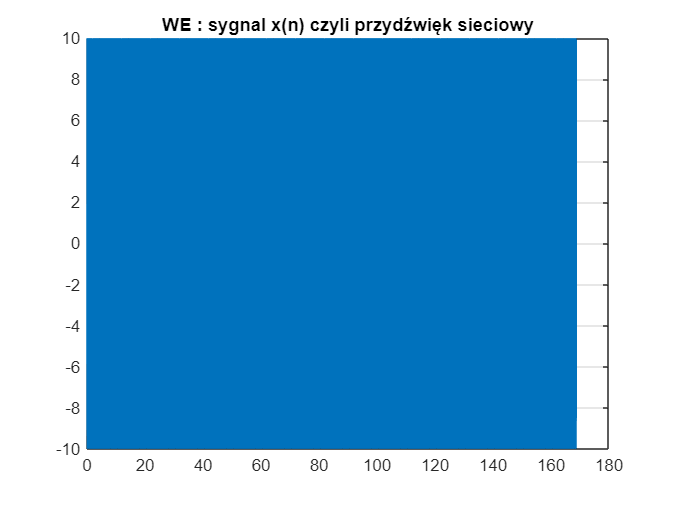

% cps_12_adapt.m

% WYBOR: SYGNALOW, ZADANIA (AIC, ASE) oraz ALGORYTMU adaptacji (LMS, NLMS, RLS) 
isig  = 2;  % SIG:  1=syntetyczny lub 2=rzeczywisty sygnal
itask = 1;  % TASK: 1=AIC adaptacyjne usuwanie interferencji
            %       2=ASE adaptacyjne odszumianie sygnalu metoda liniowej predykcji
ialg  = 2;  % ALG:  algorytm adaptacji: 1=LMS, 2=NLMS (znormalizowany LMS), 3=RLS

% INICJALIZACJA PARAMETROW FILTROW
% Filtr LMS (Least Mean Squares)
M = 50;               % liczba wag filtra
mi = 0.05;             % wspolczynnik szybkosci adaptacji ( 0<mi<1)
% Filtr NLMS (znormalizowany LMS), szybsza zbieznosc
gamma = 0.001;        % aby nie dzielic przez 0, u nas przez 0.001
% Filtr RLS (rekursywny LS) - bardziej zlozony, o wiele szybciej zbiezny
lambd = 0.999;        % RLS - wspolczynnik zapominania w funkcji kosztu LS
Rinv = 0.5*eye(M,M);  % RLS - inicjalizacja odwrotnosci macierzy Rxx

% SYGNALY TESTOWE - generacja sygnalu LFM/SFM z modulacja czestotliwosci

if(isig == 1) % SYGNALY SYNTETYCZNE =======================================

% PARAMETRY ogolne
fpr = 1000;                   % czestotliwosc probkowania
Nx = 1*fpr;                   % liczba probek
f=0:fpr/500:fpr/2;            % czestotliwosci na rysunkach
dt=1/fpr; t=0:dt:(Nx-1)*dt;   % czas na rysunkach

% SYGNAL
A = 1;            % amplituda sygnalu
f0 = 0;           % LFM: czestotliwosc poczatkowa
df = 100;         % LFM: przyrost czestotliwosci [Hz/s], SFM: glebokosc modulacji [Hz]
fc = 200;         % SFM: czestotliwosc sygnalu nosnego
fm = 1;           % SFM: czestotliwosc modulujaca sygnal nosny
s1 = A*cos( 2*pi* (f0*t + 0.5*df*t.^2) );                  % SYGNAL LFM
s2 = A*cos( 2*pi* (fc*t + df/(2*pi*fm)*cos(2*pi*fm*t) ) ); % SYGNAL SFM
s = s1;                                                    % WYBOR 

% OBWIEDNIA sygnału - kształt zmiany amplitudy
env  = 1;  % wybor obwiedni sygnalu:
           % 0=prostokatna, 1=alfa*t, 2=exp(-alfa*t), 3=gaussowska 
if (env==0)          w = boxcar(Nx)'; end            % 0 = prostokatna
if (env==1) alfa=5;  w=alfa*t;        end            % 1 = alfa*t
if (env==2) alfa=5;  w=exp(-alfa*t);  end            % 2 = exp(-alfa*t)
if (env==3) alfa=10; w=exp(-alfa*pi*(t-0.5).^2); end % 3 = gaussowska

% SYGNAL Z OBWIEDNIA
s = s .* w;

% SYGNALY WEJSCIOWE FILTRA
if (itask==1)                     % TEST 1 - usuwanie interferencji
   P = 0;                         % brak predykcji
   x = 0.1*sin(2*pi*200*t-pi/5);  % interferencja, stlumiona i opozniona
   d = s + 0.5*sin(2*pi*200*t);   % sygnal + interferencja
end
if (itask==2)                     % TEST 2 - odszumianie predykcyjne
   P = 1;                         % rzad liniowej predykcji 1,2,3,...
   x = s + 0.25*randn(1,Nx);      % sygnal + szum
   d = [ x(1+P:length(x)) 0 ];    % d = sygnal x przyspieszony o P probek
end

else % SYGNALY RZECZYWISTE ================================================
   % [s, fpr] = audioread('speech8000.wav'); s=s';
   % [sA,fpr] = audioread('speakerA.wav');   sA=sA';
   % [sB,fpr] = audioread('speakerB.wav');   sB=sB';
   P = 1;  % opoznienie w probkach
   if(itask==1)                                  % TEST 1
      s = ekg;                                    % zapamietaj do porownania 
      fpr = 128;
      dt = 1/fpr;
      Nx = length(s);
      t = dt*(0:Nx-1);
      f_przydzwiek = 50;
      % A_przydzwiek = 5;
      interferencja = 10 * sin(2*pi*f_przydzwiek*t - pi/5);
      % d(n) = oryginalny sygnal EKG + interferencja
      % x(n) = interferencja (lub jej kopia skorelowana z interferencja w d(n))
      x = interferencja;                     
      d = ekg + 10 * sin(2*pi*f_przydzwiek*t);  % dodana "kopia" echa:
   end                                           % slabsza (0.25), opozniona (P)
   if(itask==2)                            % TEST 2
      x = s; Nx = length(x);               % oryginalny, zaszumiony sygnal mowy
      d = [ x(1+P:length(x)) zeros(1,P) ]; % d = sygnal x przyspieszony o P probek
   end
   f=0:fpr/500:fpr/2;                      % czestotliwosci dla rysunkow
   dt = 1/fpr; t = dt*(0:Nx-1);            % czas dla rysunkow
end %======================================================================

% Rysunki - sygnaly wejsciowe filtra adaptacyjnego
% figure;
% subplot(211); 
plot(t,x); grid; title('WE : sygnal x(n) czyli przydźwięk sieciowy');

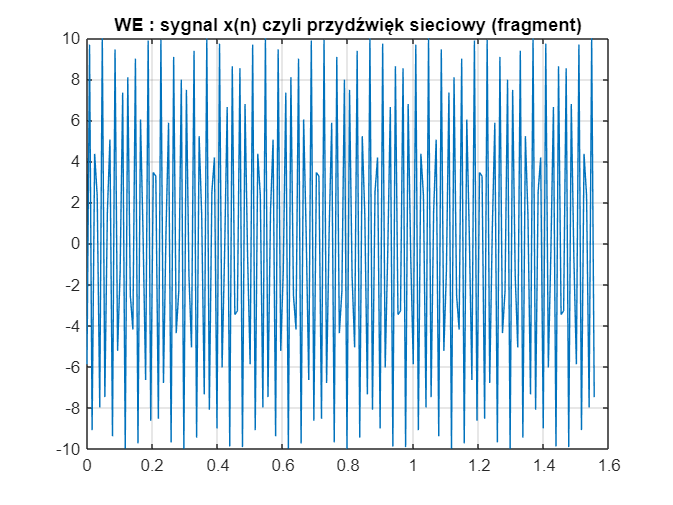

plot(t(1:200),x(1:200)); grid; title('WE : sygnal x(n) czyli przydźwięk sieciowy (fragment)');

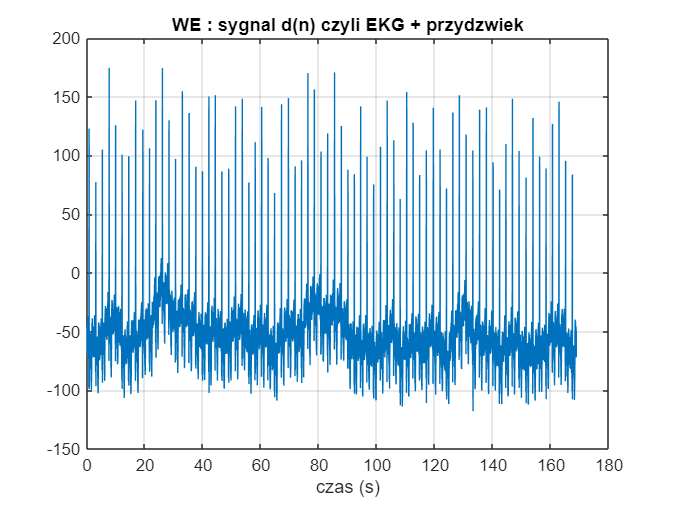

% subplot(212);
plot(t,d); grid; title('WE : sygnal d(n) czyli EKG + przydzwiek'); xlabel('czas (s)');

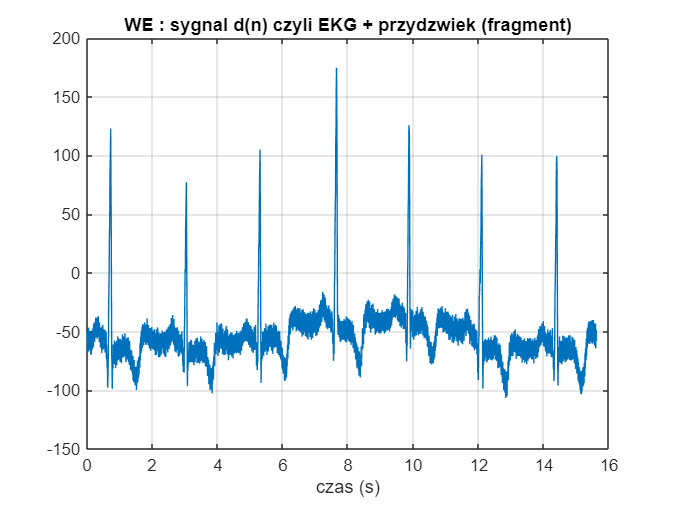

plot(t(1:2000),d(1:2000)); grid; title('WE : sygnal d(n) czyli EKG + przydzwiek (fragment)'); xlabel('czas (s)');


% TROCHE TEORII
% Obliczenie wag optymalnego filtra Wienera oraz ograniczenia na wspolczynnik mi
for k = 0 : M
  rxx(k+1) = sum( x(1+k:Nx) .* x(1:Nx-k) )/(Nx-M);  % auto-korelacja sygnalu x(n)
  rdx(k+1) = sum( d(1+k:Nx) .* x(1:Nx-k) )/(Nx-M);  % korelacja wzajemna sygnalow d(n) i x(n)
end
Rxx = toeplitz(rxx,rxx);         % symetryczna macierz autokorelacji sygnalu x(n)
h_opt = Rxx\rdx';                % wagi optymalnego filtra Wienera
lambda = eig( Rxx );             % wartosci wlasne macierzy Rxx
lambda = sort(lambda,'descend'); % sortowanie wartosci wlasnych
disp('Sugerowana wartosc mi:')

Sugerowana wartosc mi:


mi1_risc = 1/lambda(1),          % odwrotnosc maksymalnej wartosci wlasnej

mi1_risc = 7.7188e-04

mi2_risc = 1/sum(lambda),  % odwrotnosc sumy wszystkich wartosci wlasnych

mi2_risc = 3.9125e-04

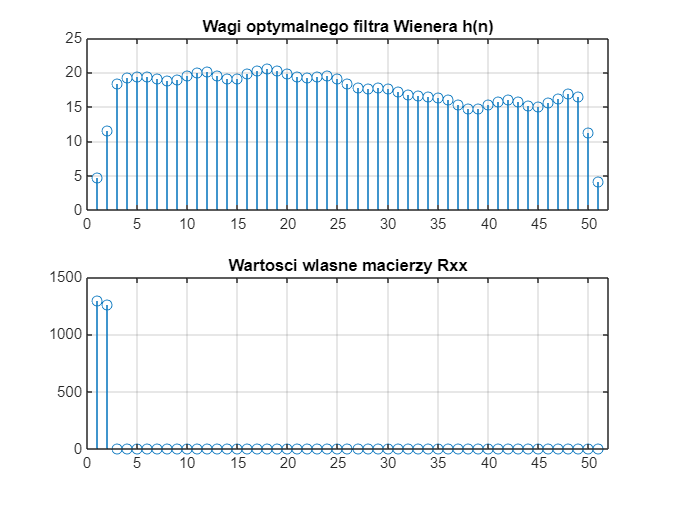

figure;
subplot(211); stem( h_opt ); grid; title('Wagi optymalnego filtra Wienera h(n)');
subplot(212); stem( lambda ); grid; title('Wartosci wlasne macierzy Rxx');

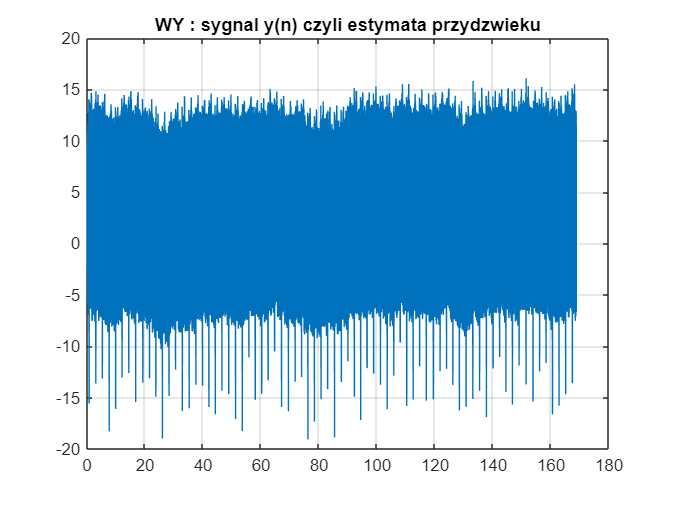

% mi = mi2_risc/20;
  
% FILTRACJA ADAPTACYJNA
bx = zeros(M,1);         % inicjalizacja bufora na probki sygnalu wejsciowego x(n)
h  = zeros(M,1);         % inicjalizacja wag filtra
e = zeros(1,Nx);         % inicjalizacja wyjscia 1
y = zeros(1,Nx);         % inicjalizacja wyjscia 2
for n = 1 : Nx                   % Petla glowna
    bx = [ x(n); bx(1:M-1) ];    % wstawienie nowej probki x(n) do bufora
    y(n) = h' * bx;              % filtracja x(n), czyli estymacja d(n)
    e(n) = d(n) - y(n);          % blad estymacji d(n) przez y(n)
    if (ialg==1)  % LMS  ########
       h = h + ( 2*mi * e(n) * bx );               % LMS  - adaptacja wag filtra
    end      
    if (ialg==2)  % NLMS ########
       eng = bx' * bx;                             % energia sygnalu w buforze bx 
       h = h + ( (2*mi)/(gamma+eng) * e(n) * bx ); % adaptacja wag filtra
    end
    if (ialg==3)  % RLS #########
       Rinv = (Rinv - Rinv*bx*bx'*Rinv/(lambd+bx'*Rinv*bx))/lambd; % nowe Rinv 
       h = h + (e(n) * Rinv * bx );                                % nowe wagi
    end
    if(0) % Obserwacja wag filtra oraz jego odpowiedzi czestotliwosciowej
       subplot(211); stem(h); xlabel('n'); title('h(n)'); grid;
       subplot(212); plot(f,abs(freqz(h,1,f,fpr))); xlabel('f (Hz)');
       title('|H(f)|'); grid; % pause
    end   
end
  
% RYSUNKI - sygnaly wyjsciowe z filtra adaptacyjnego
figure;
% subplot(211); 
plot(t,y); grid; title('WY : sygnal y(n) czyli estymata przydzwieku');

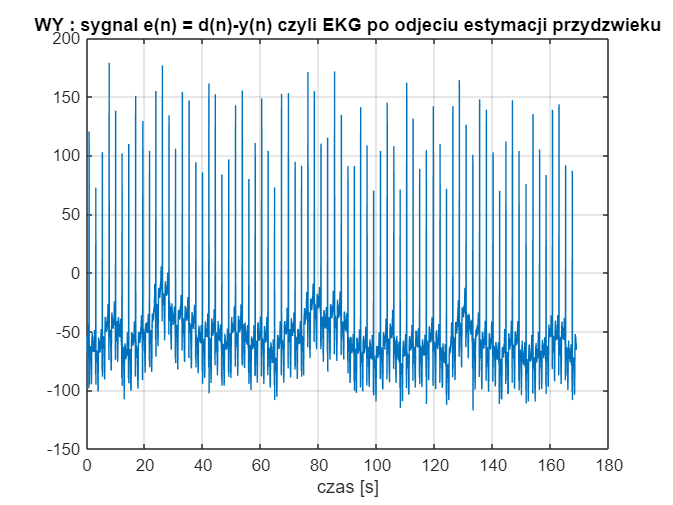

% subplot(212); 
plot(t,e); grid; title('WY : sygnal e(n) = d(n)-y(n) czyli EKG po odjeciu estymacji przydzwieku');
xlabel('czas [s]');

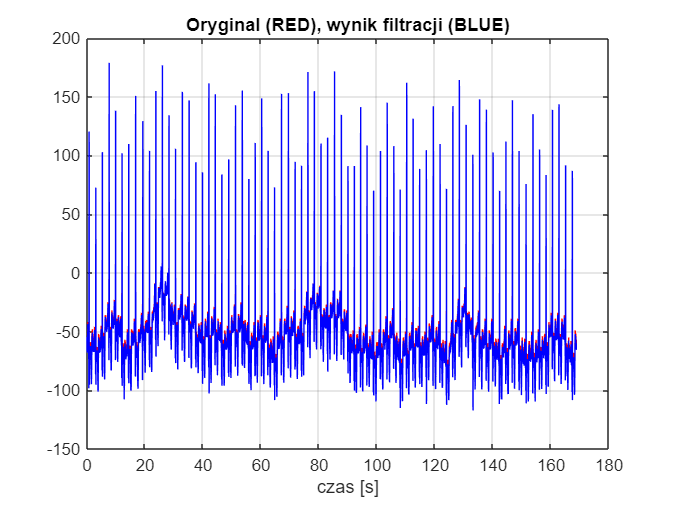

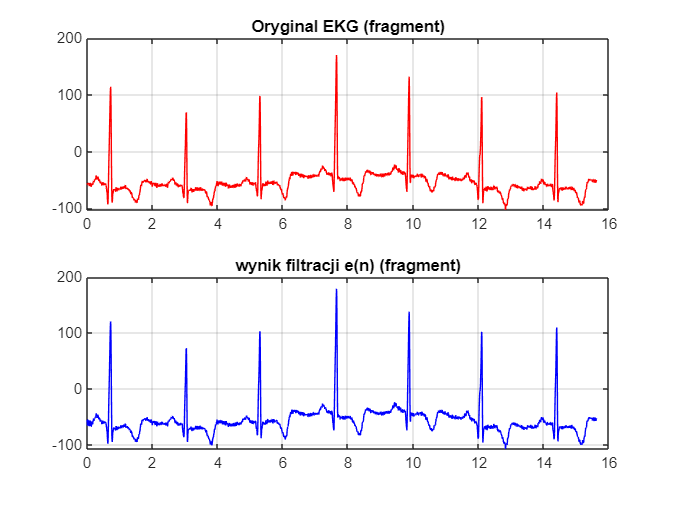

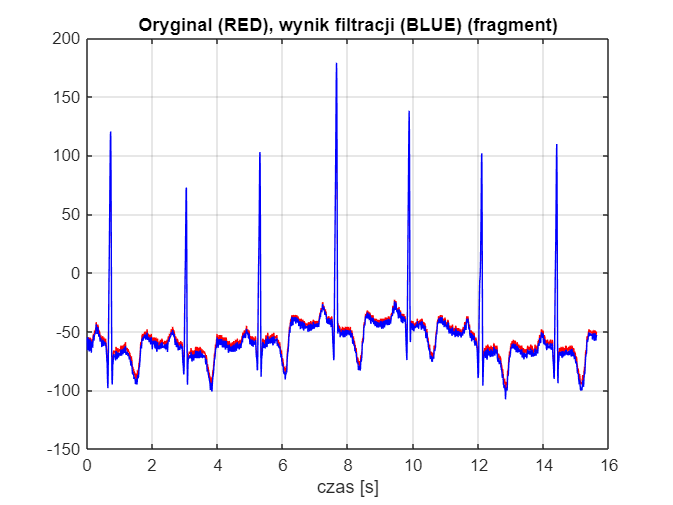

if (itask==1)
   % figure; subplot(111); 
   figure;
   plot(t,s,'r',t,e,'b'); grid; xlabel('czas [s]');
   title('Oryginal (RED), wynik filtracji (BLUE)');
   figure;
   subplot(211); plot(t(1:2000),s(1:2000),'r');
   grid; title('Oryginal EKG (fragment)');
   subplot(212); plot(t(1:2000),e(1:2000),'b');
   grid; title('wynik filtracji e(n) (fragment)');
   figure;
   plot(t(1:2000),s(1:2000),'r',t(1:2000),e(1:2000),'b'); 
   grid; xlabel('czas [s]');
   title('Oryginal (RED), wynik filtracji (BLUE) (fragment)');
end

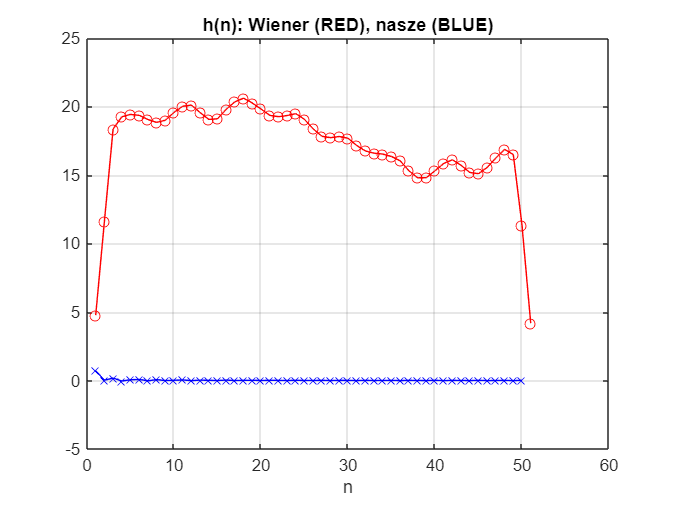

if (itask==2)
   n=Nx/2+1:Nx; 
   SNR_in_dB =  10*log10( sum( s(n).^2 ) / sum( (d(n)-s(n)).^2 ) ),
   SNR_out_dB = 10*log10( sum( s(n).^2 ) / sum( (s(n)-y(n)).^2 ) ),
   n=1:Nx-P;
   figure; subplot(111); plot(t(n),s(n),'k',t(n),d(n),'r',t(n),y(n),'b');
   grid; xlabel('czas (s)');
   title('Odniesienie (BLACK), zaszumiony (RED), odszumiony (BLUE)');
end
figure; subplot(111); plot(1:M+1,h_opt,'ro-',1:M,h,'bx-'); grid;
title('h(n): Wiener (RED), nasze (BLUE)');   xlabel('n');

% mi - wspolczynnik kroku adaptacji - od niego zalezy szybkosc zbieznosci
% ale tez stabilnosc